Step

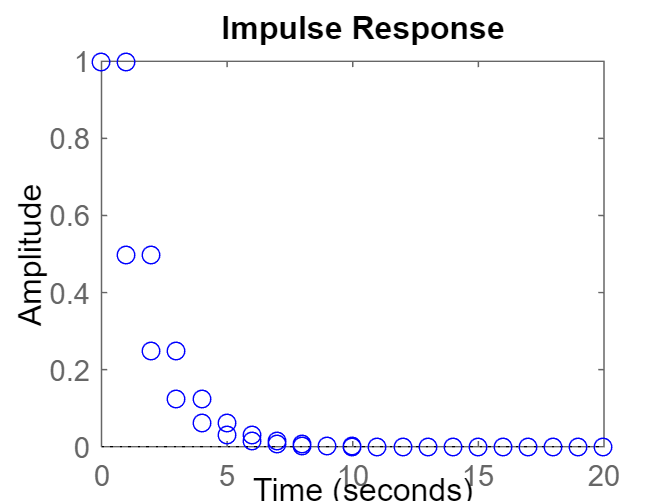

Tp = 1
z = tf('z',Tp);

G = z/(z-0.5);

impulse(G,'o')

G = z/(z-1);

G =
 
      z
  ---------
  z^6 - z^5
 
Sample time: 1 seconds
Discrete-time transfer function.



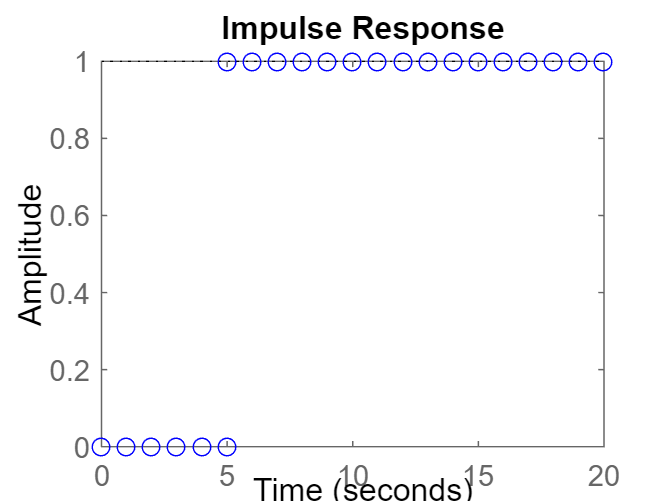

G=G*1/z^5

impulse(G,'o');

L -> Z -> y(nTp)

syms s tau f(t) n Tp z
F = 2/s/(tau*s+1)

$$F = \frac{2}{s\,\left(s\,\tau +1\right)}$$

f(t)=ilaplace(F)

$$f(t) = 2-2\,{\mathrm{e}}^{-\frac{t}{\tau }}$$

f(n*Tp)

$$ans = 2-2\,{\mathrm{e}}^{-\frac{\mathrm{Tp}\,n}{\tau }}$$

y=ztrans(f(n*Tp))

$$y = \frac{2\,z}{z-1}-\frac{2\,z}{z-{\mathrm{e}}^{-\frac{\mathrm{Tp}}{\tau }}}$$

y=2*z/(z-1)-2*z/(z-0.2)

$$y = \frac{2\,z}{z-1}-\frac{2\,z}{z-\frac{1}{5}}$$

y=iztrans(y)

$$y = 2-2\,{\left(\frac{1}{5}\right)}^{n}$$

G0(z) = Z^(-1){(z-1)/z L^(-1){G0(s)/s}}

c2d = Z ekstrapolatorem

s=tf('s');
%Input-----------------------------
G0=minreal(1/(s+1)/(s+2))

G0 =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



Tp = 1

Tp = 1

H=1;
%Input-----------------------------
G0=minreal(zpk(c2d(G0,Tp)))

G0 =
 
   0.19979 (z+0.3679)
  ---------------------
  (z-0.3679) (z-0.1353)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



G = minreal(G0/(1+G0*H))

G =
 
     0.19979 (z+0.3679)
  ------------------------
  (z^2 - 0.3034z + 0.1233)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



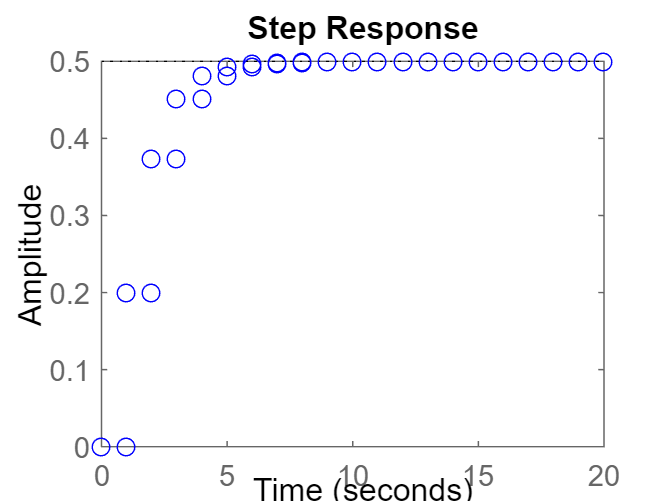

step(G0,'o')

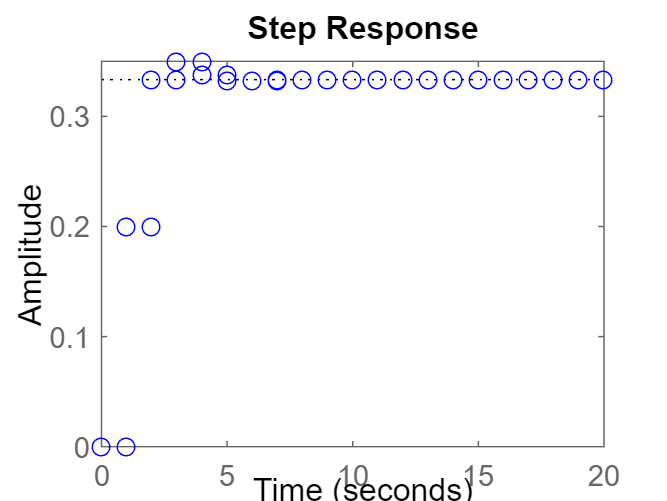

step(G,'o')


evalfr(G0,1)

ans = 0.5000

evalfr(G,1)

ans = 0.3333


[num,den]=tfdata(G,'v');
r=roots(den);
abs(r)

ans =     0.3511
    0.3511



eq=ss(G)

eq =
 
  A = 
            x1       x2
   x1   0.1517        1
   x2  -0.1003   0.1517
 
  B = 
           u1
   x1       0
   x2  0.5308
 
  C = 
           x1      x2
   y1  0.1956  0.3764
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



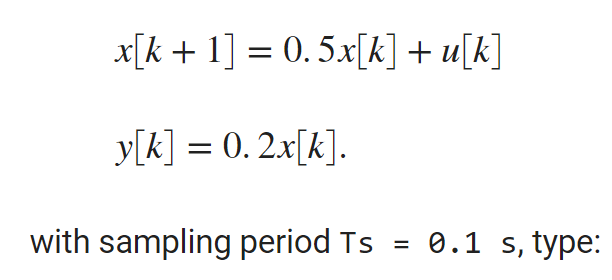

G = ss(.5,1,.2,0,0.1)

G =
 
  A = 
        x1
   x1  0.5
 
  B = 
       u1
   x1   1
 
  C = 
        x1
   y1  0.2
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.

